# Import data from MET Office Weather Data

## Aufgabe 1:

Importieren Sie den Datensatz*** MET Office Weather Data.csv*** in Matlab. Gehen Sie wie folgt vor:

- Speichern Sie die Datei lokal auf ihrem Rechner

- Öffnen Sie die Datei über den Button ***Browse for folder***

- Erzeugen Sie ein Skript für das Lesen des Datensatzes und speichern Sie dieses Skript ab.

- Dazu müssen Sie den Button ***Import Data*** verwenden.

- Studieren Sie das Skript und ändern Sie den Namen der Matlab-Variablen, welche durch den Import erzeugt wird in ***weatherD***.

- Welche Matlab Funktion wird verwendet, um die daten einzulesen?

### Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 8);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["year", "month", "tmax", "tmin", "af", "rain", "sun", "station"];
opts.VariableTypes = ["int16", "int8", "double", "double", "categorical", "double", "double", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["af", "station"], "EmptyFieldRule", "auto");

% Import the data
weatherD = readtable("C:\Users\Ioannis\Desktop\Github Repos\MATLAB\Wetterstation\MET Office Weather Data.csv", opts);

% Clear temporary variables
clear opts

## **Aufgabe 2:**

Führen Sie das erstellt Skript aus. Dadurch wird die Variable weatherD mit dem Typ Table erzeugt. Führen Sie den Befehl summary aus. Welche Informationen von Summary sind nicht hilfreich?

summary(weatherD)

Variables:

    year: 37049×1 int16

        Values:

            Min            0  
            Median      1976  
            Max         2020  

    month: 37049×1 int8

        Values:

            Min           0   
            Median        6   
            Max          12   

    tmax: 37049×1 double

        Values:

            Min             -0.9  
            Median          12.4  
            Max             28.3  
            NumMissing      1619  

    tmin: 37049×1 double

        Values:

            Min             -8.6  
            Median          5.5   
            Max             17    
            NumMissing      1542  

    af: 37049×1 categorical

        Values:

            0      16897  
            1       2425  
            10       703  
            11       663  
            12       571  
            13       499  
            14       415  
            15       367  
 

## **Aufgabe 3:**

Ergänzen Sie ihr Skript so, dass eine neue Variable wDfixed erzeugt wird, die nur noch gültigen Werte enthält. Wie viele Zeilen wurden aus der Tabelle entfernt?

% Hier wird eine neue Variable erzeugt, welche nur gültige Werte enthält.
wDfixed = rmmissing(weatherD);

% Hier wird die Anzahl der entfernten Zeilen ausgegeben.
removedRows = height(weatherD) - height(wDfixed);

## Aufgabe 4:

Erweitern Sie ihr Skript so, dass ihre Tabelle nach Jahr und Monat sortiert wird und erstellen Sie einen plot, welcher die Maximal-Temperatur über die Jahre anzeigt. Weshalb ist das Ergebnis nicht sinnvoll?

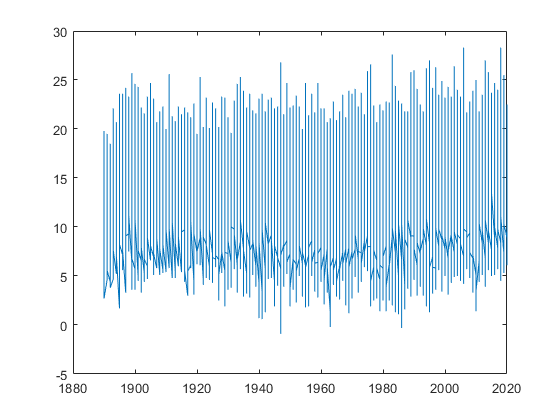

% Die Tabelle wird nach Jahr und Monat sortiert.
%sortedD = sortrows(wDfixed, [1 2]);            
sortedD = sortrows(wDfixed, {'year', 'month'});

% Hier wird die Maimxal-Temperatur über die Jahre angezeigt.
plot( sortedD.year, sortedD.tmax);

## Aufgabe 5:

Welche Wetterstation liefert die meisten Daten? Erstellen Sie eine neue Tabelle, welche ausschliesslich die Daten dieser Wetterstation beinhaltet.

% mit summary können wir das einfach ablesen
groupSum = groupsummary(wDfixed, 'station');

[maxGroupCount, index] = max(groupSum.GroupCount);
maxStation = groupSum.station(index);
maxStationD = wDfixed(wDfixed.station==maxStation,:);

## Aufgabe 6:

Erstellen Sie eine neue Tabelle, welche die durchschnittlichen Temperaturen pro Jahr enthält. Verwenden Sie die Funktion ***groupsummary(..)*** und stellen Sie die durchschnittlichen Maximal-Temperaturen seit Messbeginn in einem Plot dar. Verwenden Sie die Funktion*** 'mean'*** für die Berechnung.

## **Aufgabe 7:**

Führen Sie dieselbe Auswertung nochmals durch. Verwenden Sie diesmal aber die Funktion 'median' und zeichnen Sie den Verlauf in derselben Grafik auf. Wählen Sie einen geeigneten Markierer, um die zwei Datenreihen zu unterscheiden.

Vergleichen Sie die Daten und kommentieren Sie, Entspricht die Grafik ihren Erwartungen?

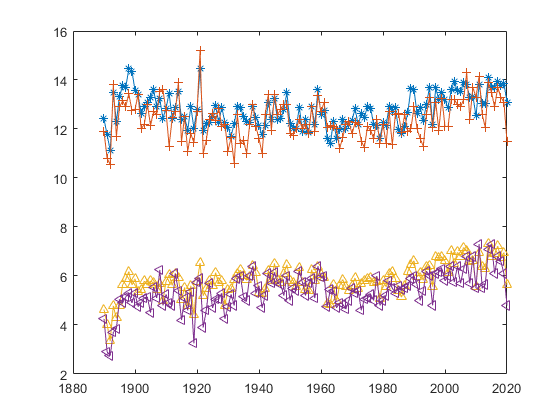

wDfixed.AvgTemp = (wDfixed.tmax + wDfixed.tmin)/2;

%in case more than one column is selected we need {}
meanTemp = groupsummary( wDfixed, 'year', {'mean','median'}, {'tmax', 'tmin'} ); 
plot(meanTemp.year, meanTemp.mean_tmax, "-*");
hold on;
plot(meanTemp.year, meanTemp.median_tmax, "-+");    
plot(meanTemp.year, meanTemp.mean_tmin, "-^" );
plot(meanTemp.year, meanTemp.median_tmin, "-<" );
hold off;

## Aufgabe 8:

Welches ist die Messstation mit der grössten mittleren Regenmenge pro Jahr, und welches ist die Messstation mit der kleinsten mittleren Regenmenge pro Jahr.

meanTempPerStation = groupsummary(wDfixed, {'station', 'year'}, {'mean', 'median'}, {'tmin', 'tmax'});
[minTs, idxMin] = min( meanTempPerStation.mean_tmin );
[maxTs, idxMax] = max( meanTempPerStation.mean_tmax );
minS = wDfixed.station(idxMin);
maxS = wDfixed.station(idxMax);

## Aufgabe 9:

Zeichnen Sie eine Scatterplot, welcher die Regenmenge und die Temperatur einer Messstation gegenüberstellt. Beschriften Sie das Diagramm mit Titel, X-Achse und Y-Achse.

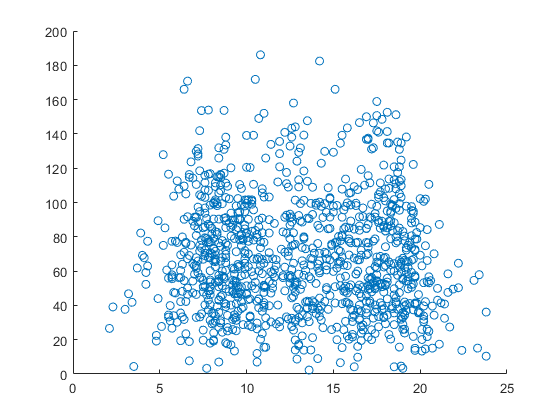

y = wDfixed( wDfixed.station == maxS, 'rain');
x = wDfixed( wDfixed.station == maxS, 'tmax');
scatter(x.tmax, y.rain );

## Aufgabe 10:

Vergleichen Sie die Maximal-Temperaturen dieser zwei Messstationen in einem Boxplot.

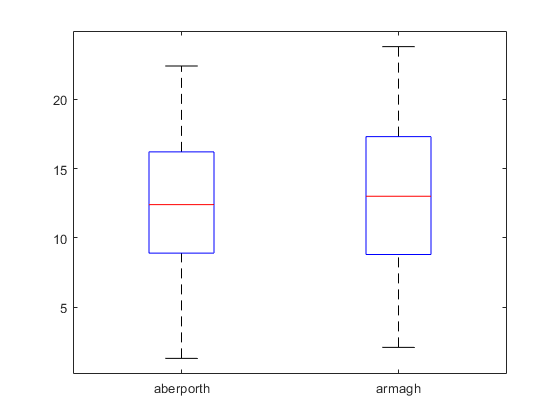

minD = wDfixed( wDfixed.station == minS, :  );
maxD = wDfixed( wDfixed.station == maxS, : );

ismember( minD, wDfixed );
minAndMaxD = union( minD, maxD);

boxplot(minAndMaxD.tmax, minAndMaxD.station);